# PART B

## PLOTTING HELPER FUNCTIONS

function plot_channel(chan, snr, mu, M)
    sgtitle(compose("Channel Plots with M = %d, μ = %0.5f, snr = %0.3f", M, mu, snr))
    % channel impulse response
    subplot(3,1,1);
    stem(chan);
    xlabel('n'); ylabel('h[n]');
    title('Channel Impulse Response h[n]');
    subtitle
    grid on;

    % channel frequency response
    subplot(3,1,2);
    [H_chan, w] = freqz(chan, 1, 1024);
    plot(w/pi, 20*log10(abs(H_chan)));
    xlabel('\omega/\pi'); ylabel('|H| (dB)');
    title('Channel Frequency Response');
    grid on;

    % channel pole zero
    subplot(3,1,3);
    zplane(chan, 1);
    title('Channel Pole-Zero Plot');
end

function plot_equalizer(gn, snr, mu, M, window)
    sgtitle(compose("Equalizer Plots with M = %d, μ = %0.5f, snr = %0.3f", M, mu, snr));

    % equalizer impulse response
    subplot(3,1,1);
    stem(gn);
    xlabel('n'); ylabel('g[n]');
    title(sprintf('Equalizer Impulse Response (M=%d)', M));
    grid on;

    % equalizer frequency response
    subplot(3,1,2);
    [G, w] = freqz(gn, 1, 1024);
    plot(w/pi, 20*log10(abs(G)));
    xlabel('\omega/\pi'); ylabel('|G| (dB)');
    title('Equalizer Frequency Response');
    grid on;

    % equalizer learning curve
    subplot(3,1,3);
    mse = conv(e.^2, ones(1,window)/window, 'same');
    figure;
    plot(10*log10(mse));
    xlabel('Iteration n'); ylabel('MSE (dB)');
    title(sprintf('Test 1: Learning Curve (M=%d, \\mu=%.4f, SNR=%ddB)', M, mu, snr_db));
    grid on;

end

## TEST 1 (INITIAL)

%% FIRST DESIRED SIGNAL
N = 1000;
n = linspace(0,N-1,N);
V = [-1, 1];
train = V(randi([1,2], 1, N));

% -- CONFIG --
snr_db = 25 % can be 20-35
h = [0.3, 1, 0.7, 0.3, 0.2];
mu = 0.01;
M = 20;
delay_idx = 2

delay_idx = 2

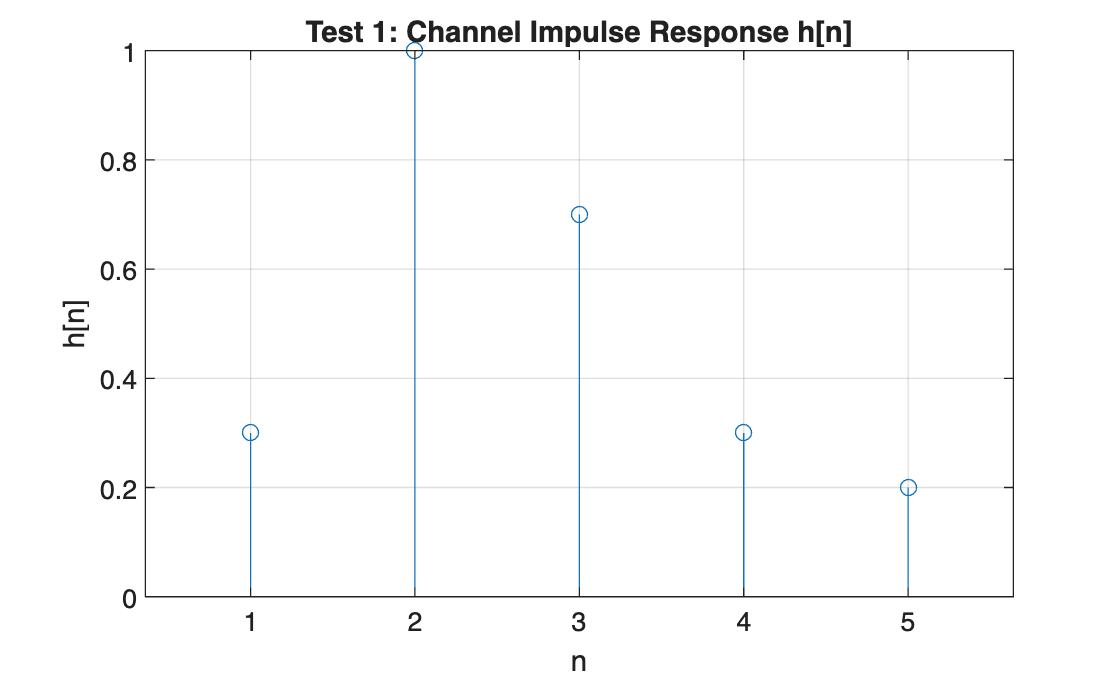

% ------------

chan_output = conv(h, train);
chan_output_trim = chan_output(1:N);
% snr_db = 10log10(signal power / noise power)
sig_power = mean(chan_output_trim.^2);
noi_power = sig_power / 10^(snr_db/10);
wn = sqrt(noi_power) .* randn(1, N);
xn = chan_output_trim + wn; % THIS IS THE NOISY CHANNEL

% signal PLOTS
figure;
stem(h);
xlabel('n'); ylabel('h[n]');
title('Test 1: Channel Impulse Response h[n]');
grid on;

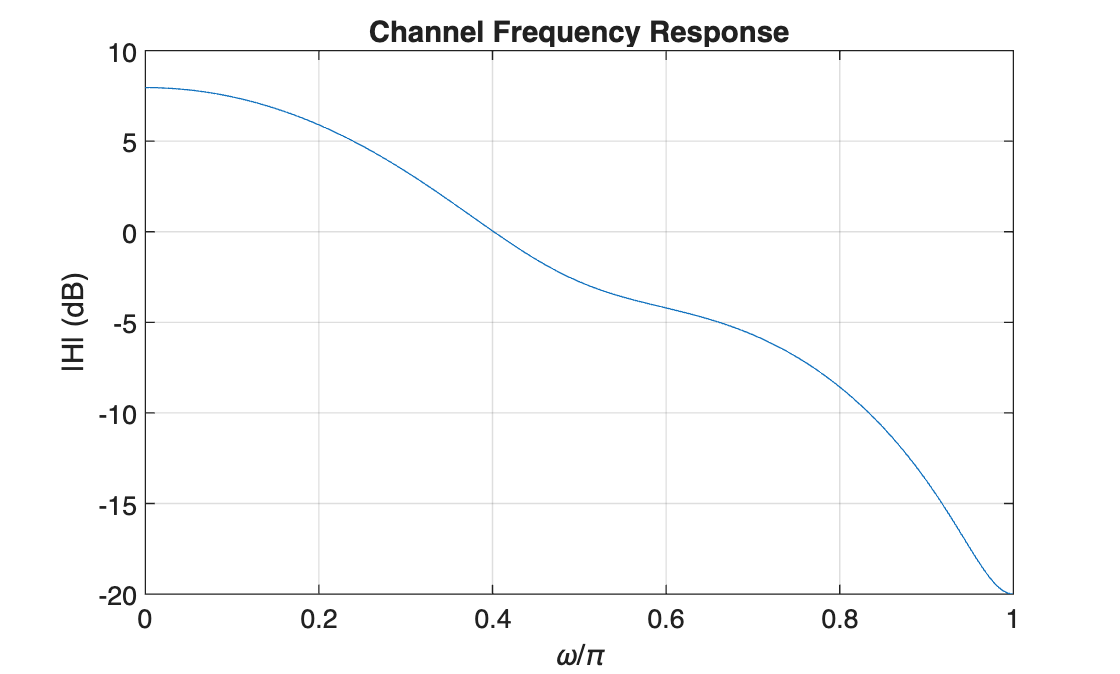


[H_chan, w] = freqz(h, 1, 1024);
figure;
plot(w/pi, 20*log10(abs(H_chan)));
xlabel('\omega/\pi'); ylabel('|H| (dB)');
title('Channel Frequency Response');
grid on;

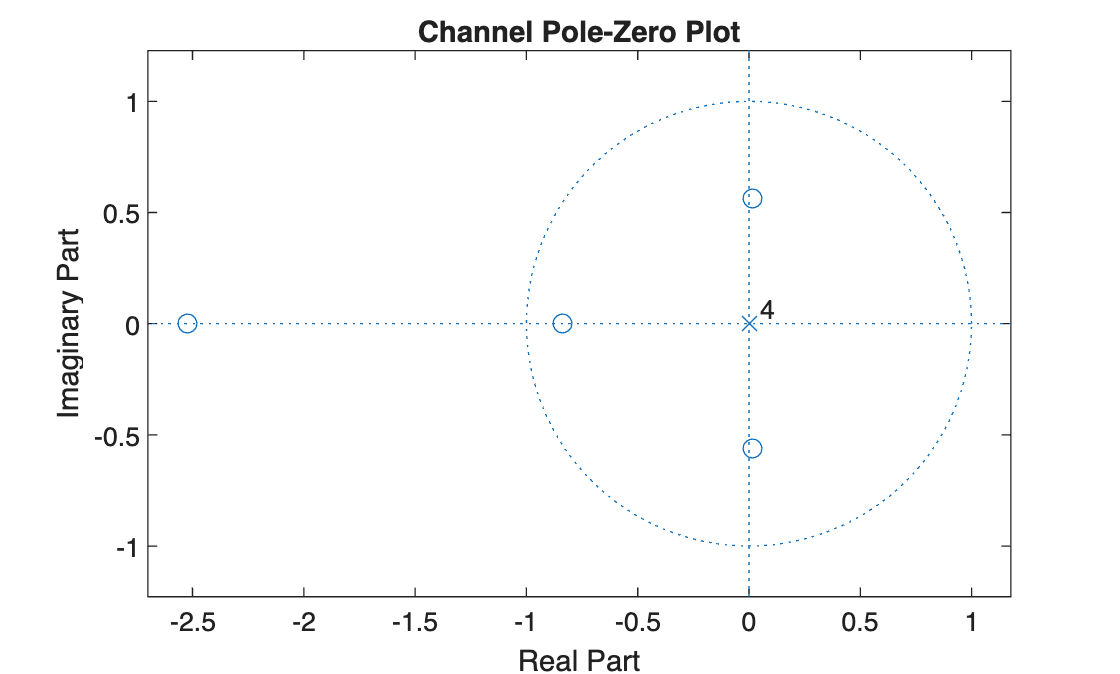


figure;
zplane(h, 1);
title('Channel Pole-Zero Plot');

% equalizer
delayed_train = [zeros(1, delay_idx), train(1:end-delay_idx)]

delayed_train =      0     0    -1     1    -1     1    -1    -1     1     1     1     1    -1    -1    -1     1     1    -1     1    -1    -1    -1     1     1    -1    -1    -1    -1     1    -1     1     1    -1     1     1    -1     1     1    -1    -1    -1    -1    -1     1     1     1    -1    -1     1     1


gn = zeros(1, M+1);
yn = zeros(1, N);
en = zeros(1, N);

for i = M+1:N
    x_inp = xn(i : -1 : i-M);
    yn(i) = gn * x_inp';
    en(i) = delayed_train(i) - y(i);
    gn = gn + 2*mu * en(i) * x_inp; % update
end

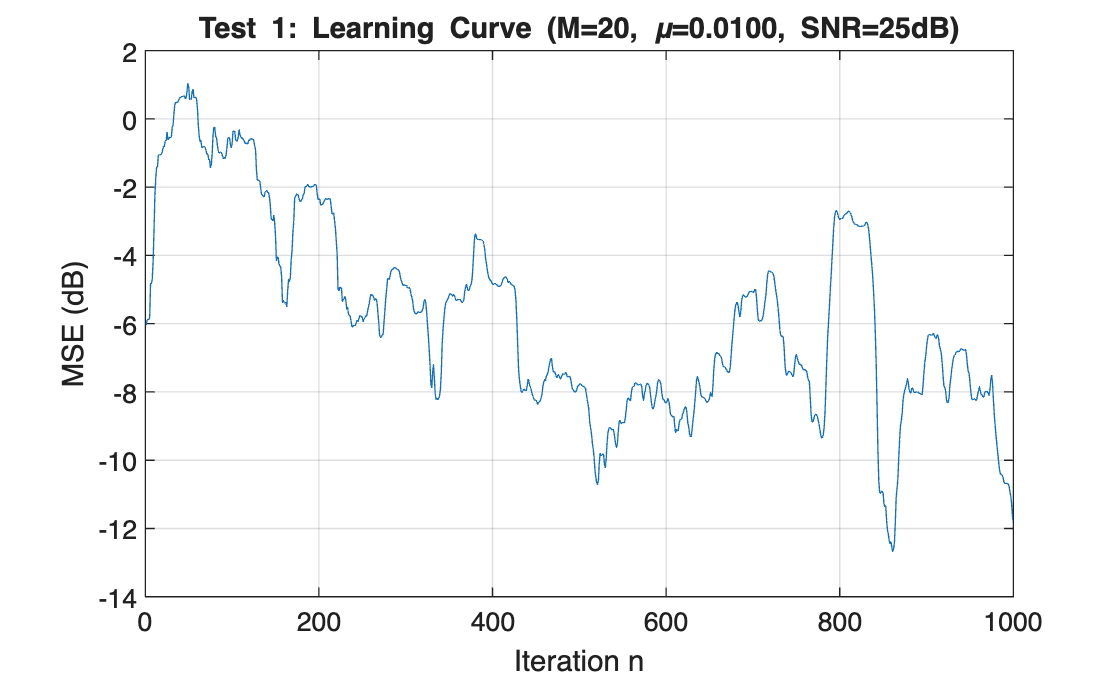

% equalizer PLOTS

% Learning curve
window = 50;
mse = conv(e.^2, ones(1,window)/window, 'same');
figure;
plot(10*log10(mse));
xlabel('Iteration n'); ylabel('MSE (dB)');
title(sprintf('Test 1: Learning Curve (M=%d, \\mu=%.4f, SNR=%ddB)', M, mu, snr_db));
grid on;

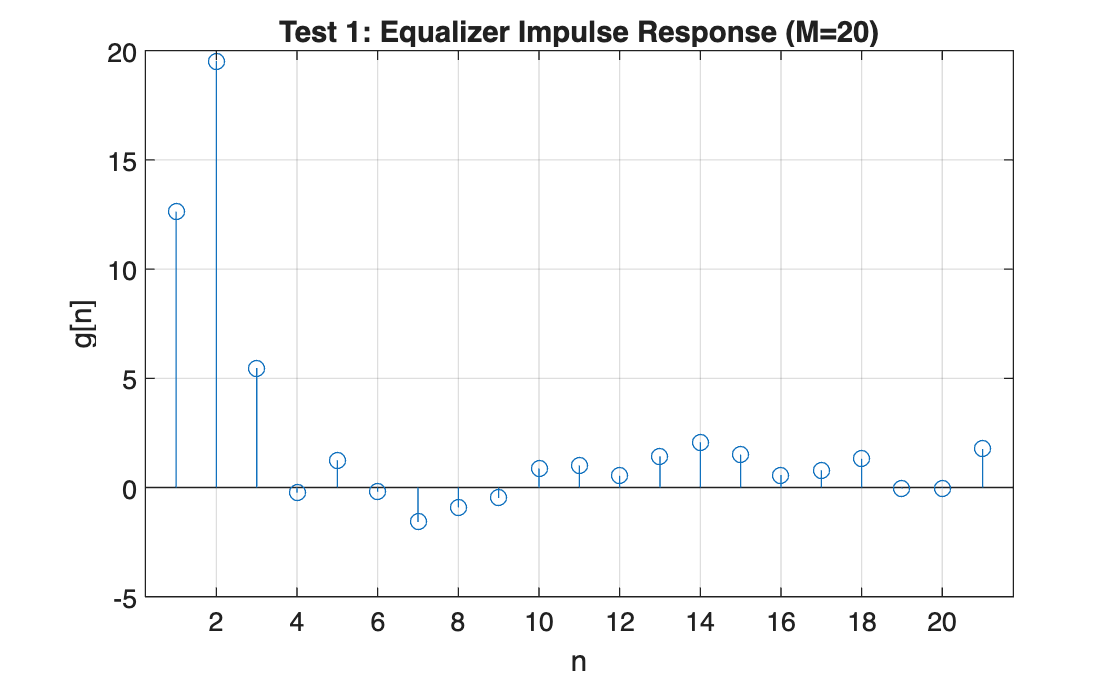


% Equalizer impulse response
figure;
stem(gn);
xlabel('n'); ylabel('g[n]');
title(sprintf('Test 1: Equalizer Impulse Response (M=%d)', M));
grid on;

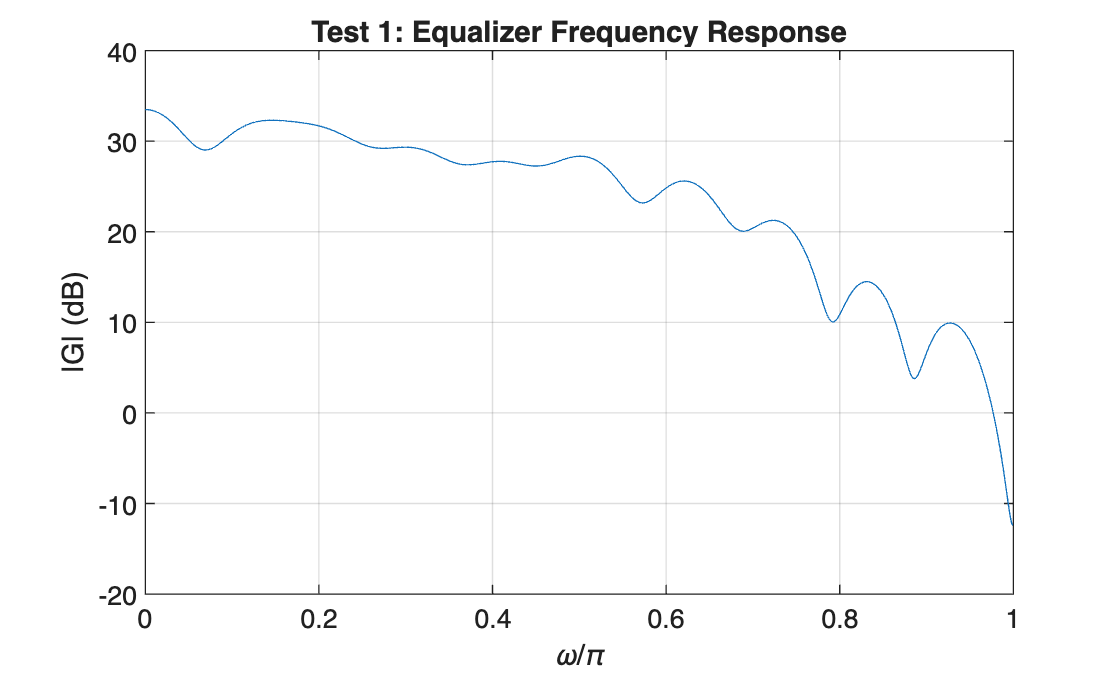


% Equalizer frequency response
[G, w] = freqz(gn, 1, 1024);
figure;
plot(w/pi, 20*log10(abs(G)));
xlabel('\omega/\pi'); ylabel('|G| (dB)');
title('Test 1: Equalizer Frequency Response');
grid on;

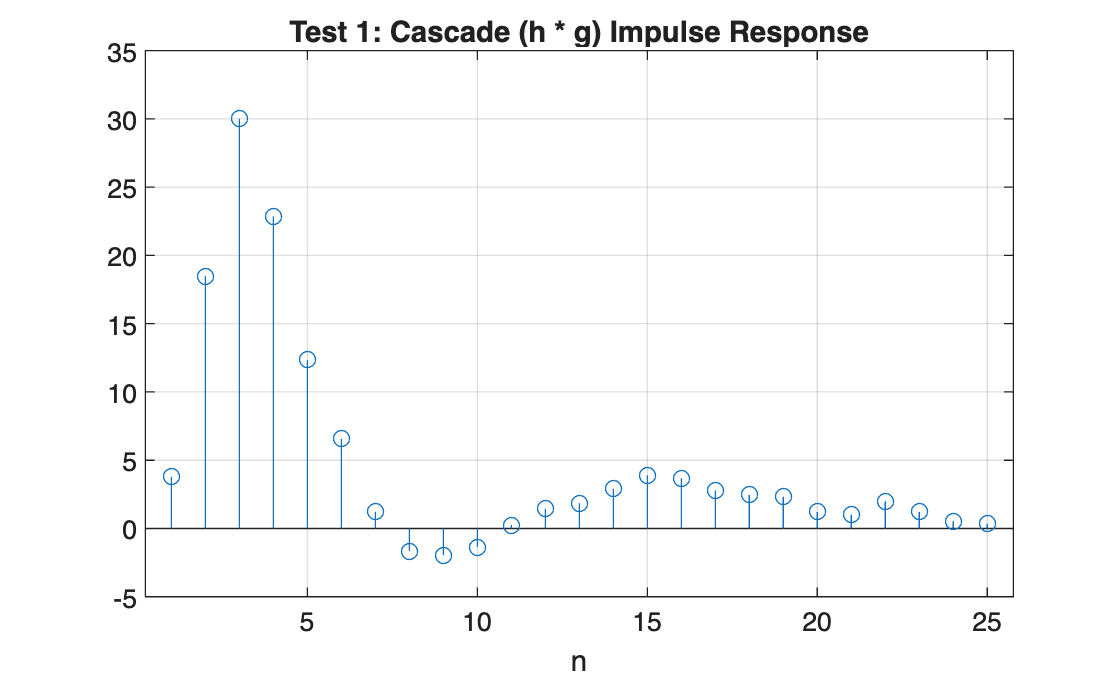


% Cascade impulse + frequency response
cascade_h = conv(h, gn);
figure;
stem(cascade_h);
xlabel('n');
title('Test 1: Cascade (h * g) Impulse Response');
grid on;

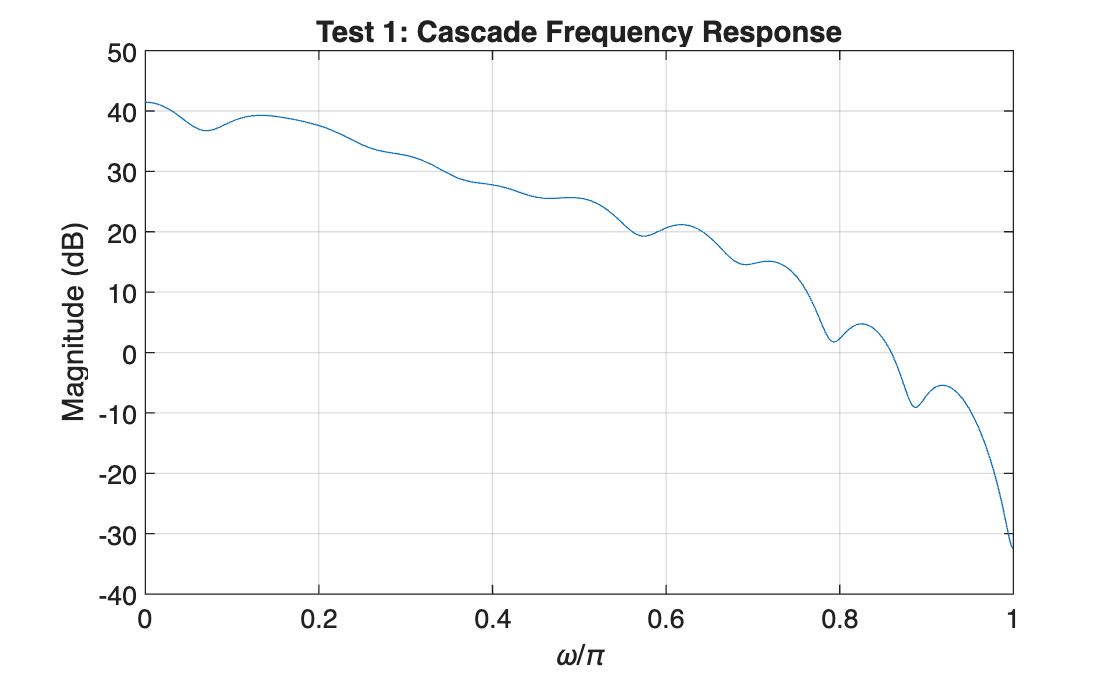


[H_cas, w] = freqz(cascade_h, 1, 1024);
figure;
plot(w/pi, 20*log10(abs(H_cas)));
xlabel('\omega/\pi'); ylabel('Magnitude (dB)');
title('Test 1: Cascade Frequency Response');
grid on;

%% bit error rate comparison on fresh test data
N_test = 5000;
s_test = V(randi([1,2], 1, N_test));
x_test = conv(s_test, h);
x_test = x_test(1:N_test);
x_test = x_test + sqrt(noi_power)*randn(1, N_test);
gn_test1 = gn;
M_test1 = M;

s_test_del = [zeros(1,delay_idx), s_test(1:N_test-delay_idx)];

% Unequalized bit error rate
dec_uneq = sign([zeros(1,delay_idx), x_test(1:N_test-delay_idx)]);
BER_uneq = sum(dec_uneq ~= s_test_del) / N_test;

% Equalized bit error rate
y_test = zeros(1, N_test);
for k = M_test1+1 : N_test
    x_vec     = x_test(k:-1:k-M_test1);  % row vector, length M+1
    y_test(k) = dot(gn_test1, x_vec);       % (1xM+1) * (M+1x1) = scalar
end

dec_eq = sign(y_test(M+1:end));
BER_eq = sum(dec_eq ~= s_test_del(M+1:end)) / (N_test-M);

fprintf('Unequalized BER: %.4f\n', BER_uneq);

Unequalized BER: 0.3808


fprintf('Equalized   BER: %.4f\n', BER_eq);

Equalized   BER: 0.1992


dec_eq = sign(y_test(M+1:end));
BER_eq = sum(dec_eq ~= s_test_del(M+1:end)) / (N_test-M);

fprintf('Test 1 BER (SNR=%ddB, M=%d, mu=%.4f)\n', snr_db, M, mu);

Test 1 BER (SNR=25dB, M=20, mu=0.0100)


fprintf('Unequalized BER: %.4f\n', BER_uneq);

Unequalized BER: 0.3808


fprintf('Equalized   BER: %.4f\n', BER_eq);

Equalized   BER: 0.1992


## FURTHER TESTS (FOR LOOP FOR FILTER ORDER, STEP SIZE, FILTER INIT, SNR, IMPULSE RESPONSE)

N = 1000;
h_tests = {[0.3,1,0.7,0.3,0.2], [1,0.5,0.2], [0.5,1,0.8,0.4,0.1,0.3]}; % 3 diff channels, all with length <= 7
snr_tests = [20, 25, 30, 35];

for h_idx = 1:length(h_tests)
    h_cur = h_tests{h_idx};
    
    for snr_db = snr_tests
        chan_out = conv(h_cur, train);
        chan_out = chan_out(1:N);
        sp       = mean(chan_out.^2);
        np       = sp / 10^(snr_db/10);
        xn_cur   = chan_out + sqrt(np)*randn(1,N);
        
        for M = [10, 20, 30]
            for mu = [0.01, 0.001, 0.0001]
                
                g_cur = zeros(1, M+1);
                y_cur = zeros(1, N);
                e_cur = zeros(1, N);
                d_cur = [zeros(1,delay_idx), train(1:N-delay_idx)];
                
                for k = M+1:N
                    xv        = xn_cur(k:-1:k-M);
                    y_cur(k)  = g_cur * xv';
                    e_cur(k)  = d_cur(k) - y_cur(k);
                    g_cur     = g_cur + 2*mu * e_cur(k) * xv;
                end
                
                final_mse = mean(e_cur(end-100:end).^2);
                fprintf('h=%d, SNR=%2ddB, M=%2d, mu=%.4f -> final MSE=%.6f\n', ...
                        h_idx, snr_db, M, mu, final_mse);


            end
        end
    end
end

h=1, SNR=20dB, M=10, mu=0.0100 -> final MSE=0.133487
h=1, SNR=20dB, M=10, mu=0.0010 -> final MSE=0.345452
h=1, SNR=20dB, M=10, mu=0.0001 -> final MSE=0.688549
h=1, SNR=20dB, M=20, mu=0.0100 -> final MSE=0.185878
h=1, SNR=20dB, M=20, mu=0.0010 -> final MSE=0.357143
h=1, SNR=20dB, M=20, mu=0.0001 -> final MSE=0.698714
h=1, SNR=20dB, M=30, mu=0.0100 -> final MSE=0.322511
h=1, SNR=20dB, M=30, mu=0.0010 -> final MSE=0.370131
h=1, SNR=20dB, M=30, mu=0.0001 -> final MSE=0.702189
h=1, SNR=25dB, M=10, mu=0.0100 -> final MSE=0.088584
h=1, SNR=25dB, M=10, mu=0.0010 -> final MSE=0.342112
h=1, SNR=25dB, M=10, mu=0.0001 -> final MSE=0.693064
h=1, SNR=25dB, M=20, mu=0.0100 -> final MSE=0.113422
h=1, SNR=25dB, M=20, mu=0.0010 -> final MSE=0.351292
h=1, SNR=25dB, M=20, mu=0.0001 -> final MSE=0.702846
h=1, SNR=25dB, M=30, mu=0.0100 -> final MSE=0.182708
h=1, SNR=25dB, M=30, mu=0.0010 -> final MSE=0.361553
h=1, SNR=25dB, M=30, mu=0.0001 -> final MSE=0.705190
h=1, SNR=30dB, M=10, mu=0.0100 -> final MSE=0.